# ディジタル制御特論課題レポート2

学籍番号: 201920765

氏名: 岩田 鉄平

## 1. 連続システムの解析

本節では，課題レポート1で導出した制御系の解析を行う．解析の結果からサンプリング周期を決定する．

### 1.1 システムのブロック図

課題1では最終的に比例微分先行型積分制御器にフィードフォワード項を追加することによって2次遅れシステムと同じ形となることを示した．システムのブロック図をFig. 1に示す．

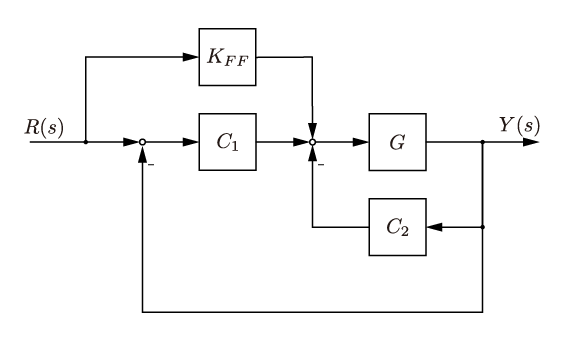

Fig. 1 System dynamics

各伝達関数は次式で表される．


$$\begin{array}{l}
G\left(s\right)=\frac{1}{s^2 -0\ldotp 04}\\
C_1 \left(s\right)=\frac{K_I }{s}\\
C_2 \left(s\right)=K_D s+K_P 
\end{array}$$


またシステム全体の伝達関数は，次式で表される．


$$G_{\textrm{ry}} =\frac{\omega_n^2 }{s^2 +2\zeta \;\omega_n +\omega_{n^2 } }$$


但し，


$$\begin{array}{l}
K_P =\omega_n^2 +2\alpha \;\zeta \;\omega_n +0\ldotp 04\\
K_I =\alpha \omega_n^2 \\
K_D =2\zeta \omega_n +\alpha \\
K_{\textrm{FF}} =\omega_n^2 
\end{array}$$


## 1.2 パラメータの決定

本節では，制御ゲインを決定するためのパラメータを選定する．

今回の制御設計では，2次遅れ系の応答を与えることで実現するものとなっている．そのため，各ゲインを直接設定することなく設定することが可能である．

設定可能なパラメータと設定した値を次に示す．


$$\begin{array}{l}
\omega_n =1\\
\zeta =1\\
\alpha =1
\end{array}$$


以降は上記パラメータを使用して進める．

## 1.3 システムの周波数応答

本節ではシステムの周波数応答を計算する．

### 1.3.1 システムの伝達関数表現

システムの伝達関数をMATLAB関数を使用して実装する．

MATLABでは，極零相殺を発生させずに宣言する．

w = 1;
z = 1;
a = 1;

Kp = w^2+2*a*z*w+0.04;
Ki = a*w^2;
Kd = 2*z*w+a;
Kff = w^2;

G = tf([1], [1 0 -0.04]);
C1 = tf([Ki], [1 0]);
C2 = tf([Kd Kp], [1]);
KFF = tf([Kff], [1]);

Gry = (KFF/C1+1)*feedback(C1*feedback(G, C2), 1);

### 1.3.2 システムの極

本節ではシステムの極零をプロットすることにより，極と零点が一致していることを確認する．

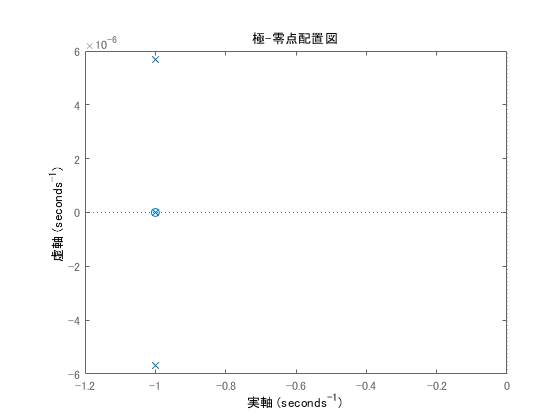

pzmap(Gry);

結果から，極の一つと零点が一致していることが確認できる．ここから，極零相殺によって2次系の応答を得ていることを確認することができる．

また，今回は$\zeta =1$という臨界減衰になるようなパラメータを選択していたが，2つの極が虚軸方向に触れていることが分かる．これは，伝達関数の計算及び極の計算の誤差であることが考えられる．

### 1.3.3 システムのボード線図

本節では，システムの周波数応答であるボード線図を示す．

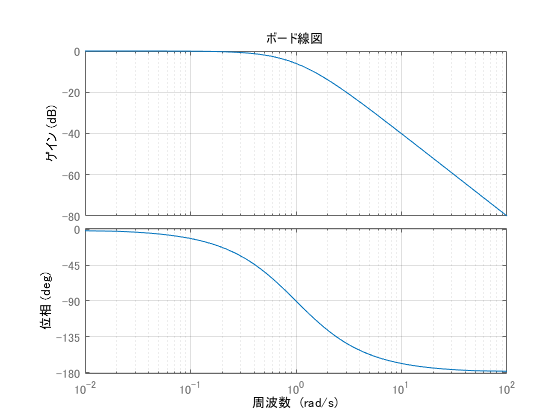

bode(Gry);
grid on;

## 2. 離散時間システムの設計

本節では，連続時間システムの離散化を行う．

### 2.1 サンプリング(制御)周期の決定

離散化を行う上でサンプリング周期が制御性能に大きく寄与することが知られている．一般的に制御周期を短くすると連続時間システムの応答と似てくるが，制御周期を短くするにはマイコンなどの性能に依存するためシステムにあった制御周期を設定する必要がある．本レポートでは，連続時間システムのゲイン線図に着目し，制御周期を決定するものとする．

ゲイン線図を見ると$\omega \;=1$の点からゲインが減衰していることが分かる．これは，制御設計時に固有角周波数$\omega_n =1$と設定したためである．ここからバンド幅は


$$f_B =\frac{\omega_n }{2\pi \;}$$


制御周期はハンド幅の1000倍を設定する


$$T_c =\frac{1}{{1000f}_B }=\frac{2\pi }{{1000\omega }_n }$$


% バンド幅の周波数を求める
wb = bandwidth(Gry);
fb = wb/(2*pi);
Tc = 1/(1000*fb);
fprintf("制御周期: %.3f[sec]", Tc);

制御周期: 0.010[sec]

以降，上記制御周期を使用して制御を行う．

### 2.2 伝達関数の離散化

本節では，制御器の離散化を行う．離散化の手法として，ステップ不偏モデル，代入モデル，極零対応モデルを使用する．制御器は$C_1$，$C_2$，$K_{\textrm{FF}}$があるが，$K_{\textrm{FF}}$は定数ゲインであるため，離散化の必要はない．

よって以降は，$C_1$，$C_2$の離散化について検討していく．

#### 2.2.1 ステップ不変モデル

ステップ不変モデルを使用した離散化を行う．

伝達関数のステップ不変モデルは次式であらわされる．


$$G\left(\epsilon \right)=\frac{\epsilon }{T_c \epsilon \;+1}\Delta \left\lbrack G\left(s\right)\frac{1}{s}\right\rbrack$$


ここで$\Delta \left\lbrack \cdot \;\right\rbrack$はデルタ変換の処理を行うとする．これをもとに$C_1$，$C_2$の変換を行う


$$C_1 \left(\epsilon \right)=$$

$$\frac{\epsilon }{T_c \epsilon \;+1}\Delta \left\lbrack C_1 \left(s\right)\frac{1}{s}\right\rbrack =\frac{\epsilon }{T_c \epsilon \;+1}\Delta \left\lbrack \frac{K_I }{s}\cdot \frac{1}{s}\right\rbrack =\frac{\epsilon }{T_c \epsilon \;+1}\cdot K_I \frac{T_c \epsilon +1}{\epsilon^2 }=\frac{K_I }{\epsilon }$$



$$C_2 \left(\epsilon \right)=\frac{\epsilon }{T_c \epsilon \;+1}\Delta \left\lbrack C_2 \left(s\right)\frac{1}{s}\right\rbrack =\frac{\epsilon }{T_c \epsilon \;+1}\Delta \left\lbrack \left(K_D s+K_P \right)\cdot \frac{1}{s}\right\rbrack =\frac{\epsilon }{T_c \epsilon \;+1}\cdot \left(K_D +K_P \frac{T_c \epsilon +1}{\epsilon }\right)=\frac{\epsilon K_D }{T_c \epsilon \;+1}+K_P$$


#### 2.2.2 代入モデル

代入モデルを使用した離散化を行う．

伝達関数の代入モデルは次式であらわされる．


$$G\left(\epsilon \right)=G\left(s\right){\left|\right.}_{s=\frac{\epsilon }{\mu T_c \epsilon +1}}$$


これをもとに$C_1$，$C_2$の変換を行う．


$$C_1 \left(\epsilon \right)=C_1 \left(s\right){\left|\right.}_{s=\frac{\epsilon }{\mu T_c \epsilon +1}} =\frac{K_I }{s}{\left|\right.}_{s=\frac{\epsilon }{\mu T_c \epsilon +1}} =\frac{K_I \left(\mu T_c \epsilon +1\right)}{\epsilon }$$



$$C_2 \left(\epsilon \right)=C_2 \left(s\right){\left|\right.}_{s=\frac{\epsilon }{\mu T_c \epsilon +1}} =$$

$$K_D s+K_P {\left|\right.}_{s=\frac{\epsilon }{\mu T_c \epsilon +1}} =\frac{K_D \epsilon }{\mu T_c \epsilon +1}+K_P$$


#### 2.2.3 極零対応モデル

極零対応モデルを使用した離散化を行う．

伝達関数の極零対応モデルは次式であらわされる．


$$G\left(s\right)=K\frac{\Pi \left(\frac{s+b_i }{b_i }\right)}{s^l \Pi \;\left(\frac{s+a_i }{a_i }\right)}\to G\left(\epsilon \right)=K\frac{\Pi \left(\frac{\epsilon +{\beta \;\;}_i }{{\beta \;}_i }\right)}{\epsilon^l \Pi \;\left(\frac{s+{\alpha \;}_i }{{\alpha \;}_i }\right)}$$


但し，


$$\begin{array}{l}
\alpha_i =\frac{1-e^{-a_i T_c } }{T_c }\\
\beta_i =\frac{1-e^{-b_i T_c } }{T_c }
\end{array}$$


これをもとに$C_1$，$C_2$の変換を行う．


$$C_1 \left(\epsilon \right)=\frac{K_I }{\epsilon }$$



$$C_2 \left(\epsilon \right)=K_P \left(\frac{K_D \epsilon +\beta \;}{\beta \;}\right)$$


但し


$$\beta =\frac{1-e^{-K_P T_c } }{T_c }$$


## 3. シミュレーションによる評価

前節で求めた離散モデルと連続モデルの合わせて4つの時間応答を比較する．

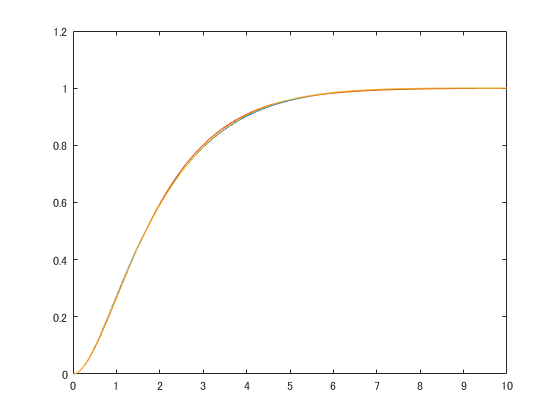

% 代入モデルのパラメータ
mu = 1/2;

% 極零対応モデルのパラメータ
a = 1e-1;
b = (1-exp(-Kp*Tc))/Tc;

% 連続時間系のシミュレーション
out = sim('twoDoF_I_PDandFF.slx');
t = out.simout.Time(:, 1);
yc = out.simout.Data(:, 2);

plot(t, yc);
hold on;
% SIMのシミュレーション
% out = sim('twoDoF_I_PDandFF_SIM.slx');
% t = out.simout.Time(:, 1);
% ySim = out.simout.Data(:, 1);
% 
% plot(t, ySim);

% 代入モデルのシミュレーション
out = sim('twoDoF_I_PDandFF_assign.slx');
t = out.simout.Time(:, 1);
yAssign = out.simout.Data(:, 1);

plot(t, yAssign);

% 極零対応モデルのシミュレーション
out = sim('twoDoF_I_PDandFF_PZM.slx');
t = out.simout.Time(:, 1);
yPZM = out.simout.Data(:, 1);

plot(t, yPZM);

## 4. まとめ

本実験では3種類の離散化手法を使用して離散化を行った．安定性は制御周期に依存するが，適切な制御周期を設定することで連続時間システムと類似した応答を得ることができる．

### 参考

本レポートのプログラムの詳細は，以下URLにある．